# **The Effect of Input Gain and The Concept of Gain Matrix**

clear all;close all; clc; format compact; format short;

### **System Definition**

            $\ddot{\mathit{\mathbf{x}}} =\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}}\right)+\mathit{\mathbf{bu}}+\mathit{\mathbf{d}}$,     $\left|\mathit{\mathbf{f}}-\hat{\mathit{\mathbf{f}}} \right|\;\le \mathit{\mathbf{F}}$,    $\left|\mathit{\mathbf{d}}\right|<\delta$ ,       $0<{\mathit{\mathbf{b}}}^- \le \mathit{\mathbf{b}}\le {\mathit{\mathbf{b}}}^+$

     where 

                1. $\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}}\right)$ is a vector valued system dynamical function.

                2. $\hat{\mathit{\mathbf{f}}} =\frac{{\mathit{\mathbf{f}}}^{-\;} +{\mathit{\mathbf{f}}}^+ }{2}$  is equal to the middle point of system estimation of system dynamics.

                3. $\mathit{\mathbf{F}}$ is the bounded sysem estimation error function.

                4. $\mathit{\mathbf{d}}$ is a vector valued bounded disturbance function

                5. $\delta$ is the disturbance bound

                6. $\mathit{\mathbf{b}}$ is the vector valued input gain with $\hat{\mathit{\mathbf{b}}} =\sqrt{{\mathit{\mathbf{b}}}^+ {\mathit{\mathbf{b}}}^- }$

**    Design:**

            $\mathit{\mathbf{n}}=2$                                                    is the system order

            $\tilde{\mathit{\mathbf{x}}} =\mathit{\mathbf{x}}-{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}}$                                           is the tracking error

            $\mathit{\mathbf{s}}={\left(\frac{\mathrm{d}}{\mathrm{d}\mathit{\mathbf{t}}}\;+\lambda \right)}^{\mathit{\mathbf{n}}-1} \tilde{\mathit{\mathbf{x}}} =\dot{\tilde{\mathit{\mathbf{x}}} } +\lambda \tilde{\mathit{\mathbf{x}}}$              is the switching surface

            $\dot{\mathit{\mathbf{s}}} =\dot{\tilde{\mathit{\mathbf{x}}} } +\lambda \tilde{\mathit{\mathbf{x}}} =\ddot{\mathit{\mathbf{x}}} -\ddot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } +\lambda \dot{\tilde{\mathit{\mathbf{x}}} } =0$                                                          sliding surface derivative

            ${\mathit{\mathbf{u}}=\;{\hat{\mathit{\mathbf{b}}} }^{-1} \left({\mathit{\mathbf{u}}}_{\mathbf{eq}} +\mathit{\mathbf{k}}\;\mathbf{sgn}\left(\mathit{\mathbf{s}}\right)+\delta \right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathit{\mathbf{u}}}_{\mathbf{eq}} =\left(-\hat{\mathit{\mathbf{f}}} +\mathit{\mathbf{d}}+\;\ddot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } -\lambda \dot{\tilde{\mathit{\mathbf{x}}} } \right)$      control signal construction

        now let's derive $\mathit{\mathbf{k}}$:

                        Take this: $0<{\mathit{\mathbf{b}}}^- \le \mathit{\mathbf{b}}\le {\mathit{\mathbf{b}}}^+$         

                                          dividie by $\hat{b} \;\;\;\;\;\;\;\;\;\;\Rightarrow$       $\sqrt{\frac{{\mathit{\mathbf{b}}}^- }{{\mathit{\mathbf{b}}}^+ }}\;\le \;\frac{\mathit{\mathbf{b}}}{\hat{\mathit{\mathbf{b}}} }\;\le \sqrt{\frac{{\mathit{\mathbf{b}}}^+ }{{\mathit{\mathbf{b}}}^- }}\;=\beta$  

                                                                            Slotine calls $\beta$ the **Gain Margin.**

            given the Lyapunov function $\mathit{\mathbf{V}}=\frac{1}{2}\;{\mathit{\mathbf{s}}}^2$ with setting its derivative to satisfy $\mathit{\mathbf{s}}\dot{\mathit{\mathbf{s}}} \le -\eta \left|\mathit{\mathbf{s}}\right|$, (with $\eta >0$) it is proven that the $\mathit{\mathbf{k}}$ gain should satisfy this equation:                                     

                                            
$$\mathit{\mathbf{k}}\ge \beta \left(\mathit{\mathbf{F}}+\eta +\delta \right)+\left(\beta -1\right)\;\left|{\mathit{\mathbf{u}}}_{\mathbf{eq}} \right|$$
 

### **Sliding Mode Design on Underwater Vehicle**

            system definition:       $\mathit{\mathbf{m}}\ddot{\mathit{\mathbf{x}}} +\mathit{\mathbf{c}}\dot{\mathit{\mathbf{x}}} \left|\dot{\mathit{\mathbf{x}}} \right|=\mathit{\mathbf{u}}$ . system constants $\mathit{\mathbf{c}}$ and $\mathit{\mathbf{m}}$ are not known accurately.

                                1. $\mathit{\mathbf{c}}$ is the drag coefficient (I assume $0\ldotp 5\le \mathit{\mathbf{c}}<1\ldotp 5$).

                                2. $\mathit{\mathbf{m}}$ is the mass of the vehicle(including the added-mass associated with the motion in a fluid)(I assume $1\le \mathit{\mathbf{m}}<2$).

                    First, let's modify the dynamics to sit in the standard form:

                                        
$$\ddot{\mathit{\mathbf{x}}} =-\frac{\mathit{\mathbf{c}}}{\mathit{\mathbf{m}}}\dot{\mathit{\mathbf{x}}} \left|\dot{\mathit{\mathbf{x}}} \right|+\frac{1}{\mathit{\mathbf{m}}}\mathit{\mathbf{u}}$$


                    Therefore,

                                    
$$\left\lbrace \begin{array}{ll}
\hat{\mathit{\mathbf{f}}} =-\hat{\frac{\mathit{\mathbf{c}}}{\hat{\mathit{\mathbf{m}}} }} \;\dot{\mathit{\mathbf{x}}} \left|\dot{\mathit{\mathbf{x}}} \right| & \\
{\mathit{\mathbf{u}}}_{\mathbf{eq}} =-\hat{\mathit{\mathbf{f}}} +\ddot{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{d}}} } -\lambda \dot{\tilde{\mathit{\mathbf{x}}} }  & 
\end{array}\right.$$
        
$$\Rightarrow \;\;\;\;\;\mathit{\mathbf{u}}={\left(\frac{1}{\hat{\mathit{\mathbf{m}}} }\right)}^{-1} \left(\hat{\mathit{\mathbf{u}}} -\mathit{\mathbf{k}}\;\mathbf{sgn}\left(\mathit{\mathbf{s}}\right)\right)$$
 

                                                    other variables:  $\left\lbrace \begin{array}{ll}
\mathit{\mathbf{k}}=\beta \left(\mathit{\mathbf{F}}+\eta \right)+\left(\beta -1\right)\left|\hat{\mathit{\mathbf{u}}} \right|\;\;\;\;\;,\;\;\;\;\;\;\;\;\;\;\;\;\;\; & \mathit{\mathbf{F}}=\dot{\mathit{\mathbf{x}}} \left|\dot{\mathit{\mathbf{x}}} \right|\\
\dot{\mathit{\mathbf{s}}} =\dot{\tilde{\mathit{\mathbf{x}}} } +\lambda \tilde{\mathit{\mathbf{x}}}  & 
\end{array}\right.$

% Design Parameters
Ctrl.Params.eta      =5;        % Controller Eta Param
Ctrl.Params.lambda   =5;        % Controller Lambda Param
Ctrl.Desired.S       = @sin;                             % Desired Trajectory
Ctrl.Desired.dS      = @cos;                             % Desired Trajectory Derivative
Ctrl.Desired.ddS     = @(x) -sin(x);                     % Desired Trajectory 2nd Derivative
Ctrl.System.m        = @(t) 1.5 + 0.5*sin(t);            % System a(t) Param
Ctrl.System.c        = @(t)   1 + 0.5*sin(t);            % System a(t) Param


% Solve ODE for the System Output
tSpan = [0, 20];
x0 = rand(1, 2);
[t, x] = ode23(@(t,x) ODE(t, x, Ctrl), tSpan, x0);

% Get the Sliding Surface and the Control Signal
u    = zeros(numel(t), 1);
s    = zeros(numel(t), 1);
Traj = zeros(numel(t), 1);
for i = 1:numel(t)
    [~, u(i), s(i), Traj(i)] = ODE(t(i), x(i, :), Ctrl);
end


%% ODE Function
function [dx, u, s, Traj] = ODE(t, x, Ctrl)
    % Unpack States
    x1 = x(1);
    x2 = x(2);

    % Calculate Trajectory
    Traj.xd   = Ctrl.Desired.S(t);
    Traj.dxd  = Ctrl.Desired.dS(t);
    Traj.ddxd = Ctrl.Desired.ddS(t);

    % Error Calc (X_tilde)
    Err  = x1 - Traj.xd;        % Error
    dErr = x2 - Traj.dxd;       % Error Derivative

    % Switching Surface
    s = dErr + Ctrl.Params.lambda * Err;

    % Control Signal Creation
    c_hat = 1;
    m_hat = 1.5;
    f_hat = c_hat / m_hat * x2 * abs(x2);
    u_eq  = -f_hat + Traj.ddxd - Ctrl.Params.lambda * dErr;

    F = x2 * abs(x2);

    % Input Gain Beta Calc
    m_min = 1;
    m_max = 2;
    beta  = sqrt((1/m_min) * (1/m_max));

    k = beta * (F + Ctrl.Params.eta) + (beta - 1) * abs(u_eq);
    u = 1/beta * (u_eq - k * sign(s));

    % State Derivative
    dx = [x2; -Ctrl.System.c(t)/Ctrl.System.m(t) * x2 * abs(x2) + u/Ctrl.System.m(t)];

    Traj = Traj.xd;
end

## Plotting

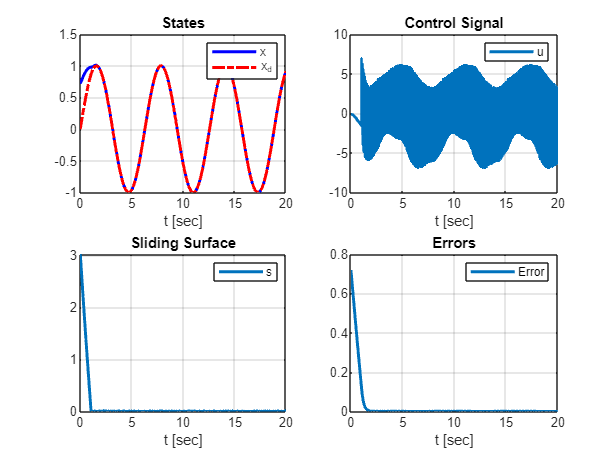

subplot(221)
plot(t, x(:, 1), 'b', t, Traj, 'r-.', 'LineWidth', 2)
grid on, legend('x', 'x_d'), title('States'), xlabel('t [sec]')

subplot(222)
plot(t, u, 'LineWidth', 2)
grid on, legend('u'), title('Control Signal'), xlabel('t [sec]')

subplot(223)
plot(t, s, 'LineWidth', 2)
grid on, legend('s'), title('Sliding Surface'), xlabel('t [sec]')

subplot(224)
plot(t, x(:, 1) - Traj, 'LineWidth', 2)
grid on, legend('Error'), title('Errors'), xlabel('t [sec]')